% Given variables
volume_fraction = 0.3;              % Volume fraction (as a decimal)
fiber_diameter_cm = 0.0032;         % Diameter of fibers (in cm)
matrix_length_cm = 12;               % Length of the matrix (in cm)
matrix_width_cm = 2;               % Width of the matrix (in cm)

% Convert diameter from cm to arbitrary units (assuming 1 cm = 100 units)
fiber_diameter = fiber_diameter_cm * 100;

% Calculate total volume of fibers
total_fiber_volume = volume_fraction * matrix_length_cm * matrix_width_cm;

% Calculate total volume of matrix
total_matrix_volume = matrix_length_cm * matrix_width_cm;

% Calculate total number of fibers
total_fibers = round(total_fiber_volume / (pi * (fiber_diameter)^2));

% Initialize fiber positions
fiber_positions = zeros(total_fibers, 2);

% Set position of the first fiber at (0, 0)
fiber_positions(1, :) = [0, 0];

% Generate random positions for the remaining fibers within the matrix
for i = 2:total_fibers
    % Generate a random position for the fiber
    new_fiber_position = rand(1, 2) .* [matrix_length_cm, matrix_width_cm];
    
    % Check minimum distance to all previously generated fibers
    min_distance = fiber_diameter; % Minimum distance between fibers
    for j = 1:i-1
        % Calculate distance to previously generated fiber
        distance = sqrt((new_fiber_position(1) - fiber_positions(j, 1))^2 + ...
                        (new_fiber_position(2) - fiber_positions(j, 2))^2);
        % Update minimum distance if needed
        if distance < min_distance
            min_distance = distance;
        end
    end
    
    % Ensure minimum distance is satisfied
    while min_distance < fiber_diameter
        % If the minimum distance criterion is not met, regenerate the fiber position
        new_fiber_position = rand(1, 2) .* [matrix_length_cm, matrix_width_cm];
        min_distance = fiber_diameter; % Reset minimum distance
        for j = 1:i-1
            % Recalculate distance to previously generated fiber
            distance = sqrt((new_fiber_position(1) - fiber_positions(j, 1))^2 + ...
                            (new_fiber_position(2) - fiber_positions(j, 2))^2);
            % Update minimum distance if needed
            if distance < min_distance
                min_distance = distance;
            end
        end
    end
    
    % Store fiber position
    fiber_positions(i, :) = new_fiber_position;
end

% Display fiber positions in the command window
disp('Fiber Positions:');

Fiber Positions:


disp(fiber_positions);

         0         0
    4.8550    0.8967
    4.3898    1.5270
    7.5348    1.5440
   11.1942    1.9455
    2.3043    0.2777
    8.3552    0.1876
    6.3049    1.0607
   10.3337    0.9697
    4.7215    1.3429
    8.8951    1.0401
    4.1726    0.3000
    7.0331    0.5243
    0.5334    1.5099
    2.9134    0.8848
    8.2536    0.7185
    8.2010    1.4081
    5.3077    0.0392
    3.9703    0.8486
    3.2432    0.3941
    9.8607    0.8598
   10.6533    0.7824




% Display results
disp(['Total Number of Fibers: ', num2str(total_fibers)]);

Total Number of Fibers: 22


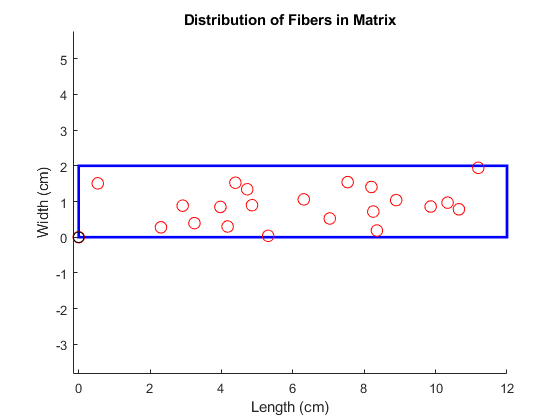


% Plot fibers
figure;
hold on;
rectangle('Position', [0, 0, matrix_length_cm, matrix_width_cm], 'EdgeColor', 'b', 'LineWidth', 2);
for i = 1:total_fibers
    fiber_x = fiber_positions(i, 1);
    fiber_y = fiber_positions(i, 2);
    rectangle('Position', [fiber_x - fiber_diameter/2, fiber_y - fiber_diameter/2, fiber_diameter, fiber_diameter], 'Curvature', [1, 1], 'EdgeColor', 'r');
end
plot(0, 0, 'ko', 'MarkerSize', 8); % Plot the first fiber location
xlabel('Length (cm)');
ylabel('Width (cm)');
title('Distribution of Fibers in Matrix');
axis equal;
hold off;hold off;